# Lab random signal processing

#### Luis Machado

#### Yan [please put surname here]

## S1: Autocorrelation estimators

Objectives of the first lab session: discovery of the topic, reliable estimation of the autocorrelation, criteria to determine the voiced or unvoiced nature of a sound

### 1) sample data

Here we created the random proceses we know the autocorrelation function

First we need some constants, to all the programs to work

clearvars
close all
clc
%Number of samples of the noise
N = 50;

%Maximun number of p shifts
P_max = N-1;

%sampling frequency and period
Fs = 10000;
Ts = 1./Fs;

%Unvoiced file names
unvoiced_names = [...
    "data/nonvoise_ch.flac" "data/nonvoise_hw.flac" ...
    "data/nonvoise_kss.flac" "data/nonvoise_th.flac" ...
    ];

%Unvoiced audios and Ts
[unvoiced_audios, unvoiced_Ts] = audioReadChain(unvoiced_names,1024);

%voiced file names
voiced_names = [...
    "data/voise_nng.flac" "data/voise_oo.flac" ...
    "data/voise_ooo.flac" ...
    ];

%Voiced audios and Ts
[voiced_audios, voiced_Ts] = audioReadChain(voiced_names,1024);


White Noise (normaly distributed):

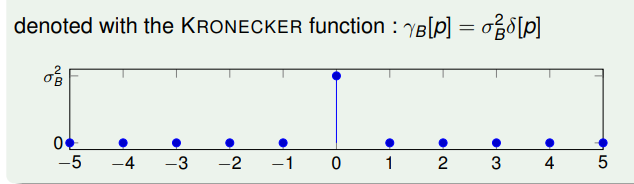

white_noise_variance = 1;
white_noise_deviation = sqrt(white_noise_variance);
white_noise_mean = 0;

white_noise = white_noise_mean + white_noise_deviation .*randn(1,N);

white_noise_autocorr = zeros(1,N);
white_noise_autocorr(1) = white_noise_variance;

AR(1) Function:

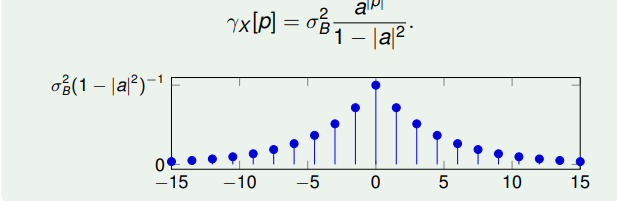

AR1_variance = 1;
AR1_deviation = sqrt(AR1_variance);
AR1_coefficient = 0.9;

AR1 = filter(1, [1 -AR1_coefficient],AR1_deviation.*randn(1,N));

AR1_autocorr = AR1_variance .* AR1_coefficient.^abs(0:P_max);
AR1_autocorr = AR1_autocorr./ (1-abs(AR1_coefficient).^2);

Sine wave with random phase (uniformaly distributed):

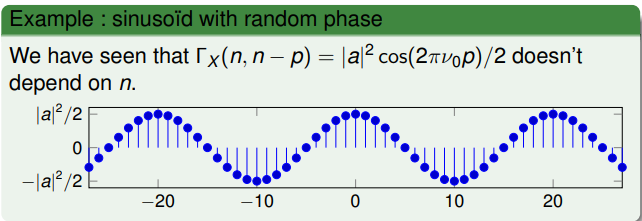

sine_amplitude = 2;
sine_reduced_frequency = 0.20; % range [0,0.5)
sine_phase_shifts = 2.*pi.*rand(1,N);
sine_angules = 2.*pi.*sine_reduced_frequency.*(1:N);

sine = sine_amplitude.*sin(sine_angules + sine_phase_shifts);
sine_pure = sine_amplitude.*sin(sine_angules);

sine_autocorr = (abs(sine_amplitude).^2) ./ 2;
sine_autocorr = sine_autocorr .* cos(2.*pi.*sine_reduced_frequency.*(0:P_max));
sine_pure_autocorr = (abs(sine_amplitude).^2) ./ 2;
sine_pure_autocorr = sine_pure_autocorr .* cos(2.*pi.*sine_reduced_frequency.*(0:P_max));

Now we graph them

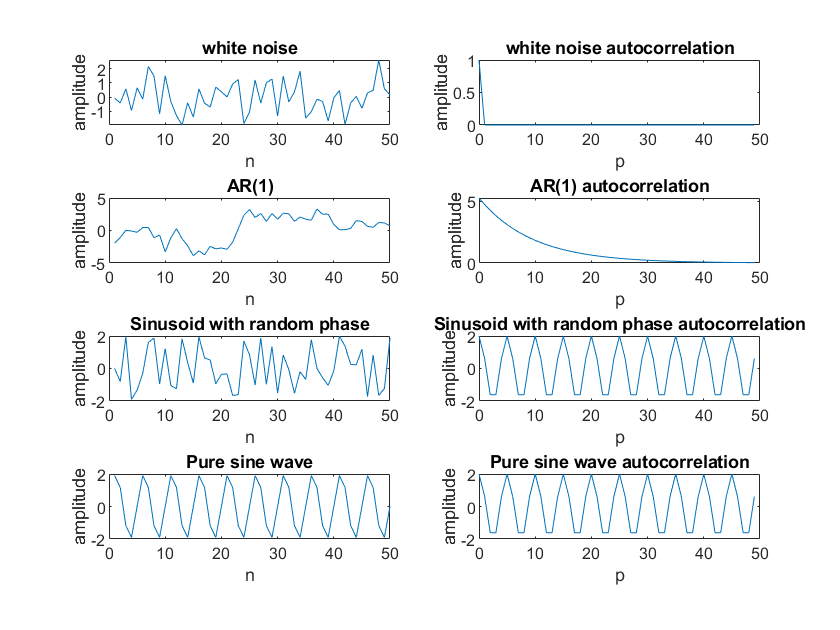

%plot
figure(1)
x_axis_n = 1:N;
x_axis_p = 0:P_max;

subplot(4,2,1)
plot(x_axis_n,white_noise)
title("white noise")
xlabel("n"), ylabel("amplitude")

subplot(4,2,2)
plot(x_axis_p,white_noise_autocorr)
title("white noise autocorrelation")
xlabel("p"), ylabel("amplitude")

subplot(4,2,3)
plot(x_axis_n,AR1)
title("AR(1)")
xlabel("n"), ylabel("amplitude")

subplot(4,2,4)
plot(x_axis_p,AR1_autocorr)
title("AR(1) autocorrelation")
xlabel("p"), ylabel("amplitude")

subplot(4,2,5)
plot(x_axis_n,sine)
title("Sinusoid with random phase")
xlabel("n"), ylabel("amplitude")

subplot(4,2,6)
plot(x_axis_p,sine_autocorr)
title("Sinusoid with random phase autocorrelation")
xlabel("p"), ylabel("amplitude")

subplot(4,2,7)
plot(x_axis_n,sine_pure)
title("Pure sine wave")
xlabel("n"), ylabel("amplitude")

subplot(4,2,8)
plot(x_axis_p,sine_pure_autocorr)
title("Pure sine wave autocorrelation")
xlabel("p"), ylabel("amplitude")

### 2) Biased autocorrelation estimator

we created a funcion (inside its own script) to implement the Biased autocorrelation estimator$^{1}$. 

Inputs:

- `X`: vector of signal samples

-  `pmax`: maximal amount of shift to be considered (optional, defaults to the length of X minus 1)

Outputs:

- `Cx`: vector of cross correlation samples for shifts varying from 0 to pmax

- `p`: vector of corresponding shifts

$^{1}$[We decided to not change the name of the function, but we think that the name is not the correct one. The title of the section is biased autocorrelation estimator, but the function is caled biased cross correlation, and only accepts one vector of signal samples].


$$\widehat{\gamma_{\mathrm{Xb}} } \left(p,\omega \right)\frac{1}{N}\sum_{k=p}^{N-1} X\left(k,\omega \right){X\left(k,\omega \right)}^*$$


#### testing

Now we test this stimator against the real autocorrelation of the functions:

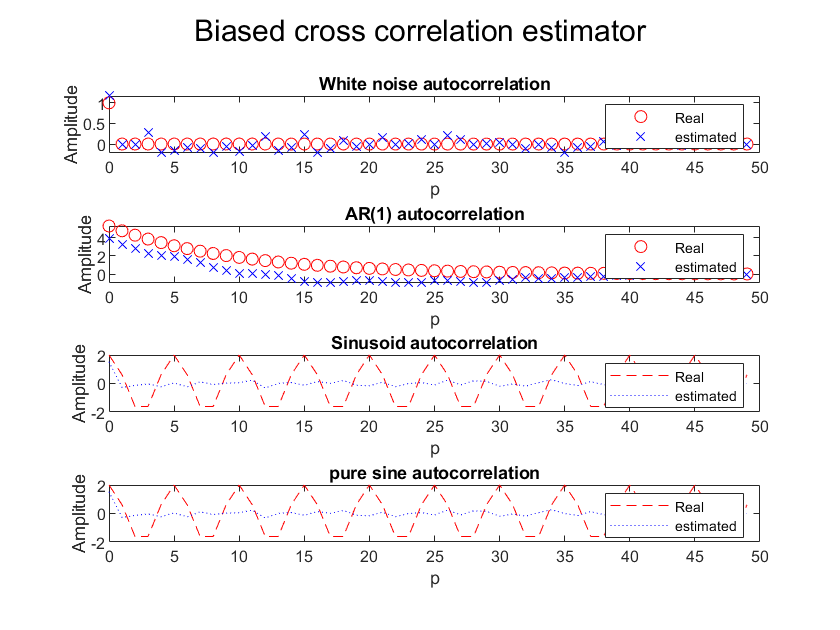

%plot
figure(2)
sgtitle("Biased cross correlation estimator")
est_white_noise = BiasedCrossCorr(white_noise);
est_AR1 = BiasedCrossCorr(AR1);
est_sine = BiasedCrossCorr(sine);
est_sine_pure = BiasedCrossCorr(sine_pure);

subplot(4,1,1) 
plot(x_axis_p,white_noise_autocorr,"ro")
hold on
plot(x_axis_p,est_white_noise,"bx")
title("White noise autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

subplot(4,1,2)
plot(x_axis_p,AR1_autocorr,"ro")
hold on
plot(x_axis_p,est_AR1,"bx")
title("AR(1) autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

subplot(4,1,3)
plot(x_axis_p,sine_autocorr,"r--")
hold on
plot(x_axis_p,est_sine,"b:")
title("Sinusoid autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

subplot(4,1,4)
plot(x_axis_p,sine_pure_autocorr,"r--")
hold on
plot(x_axis_p,est_sine,"b:")
title("pure sine autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

Then, were are the questions and the answers:

- For random processes for which you know the theoretical autocorrelation function, does the biased estimator converge when the number of samples grows? 

Yes:

N=50

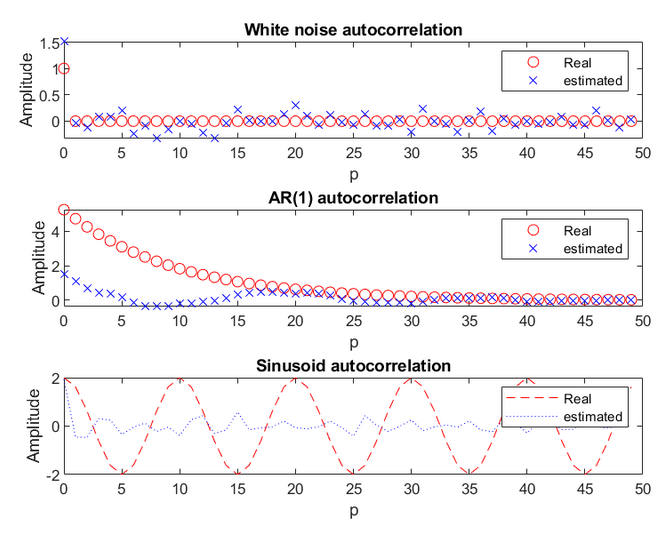

N=500 (First 50 values)

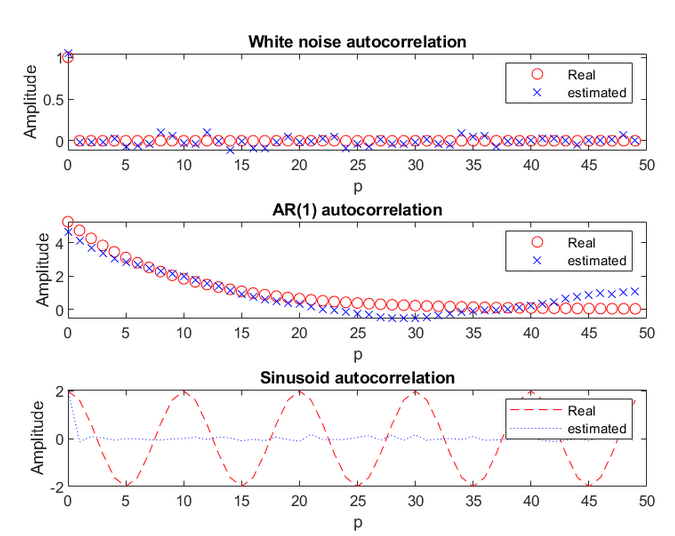

- Can you observe the effect of the bias through certain examples? 

There seems to be some problems with the sinusoid, and the values of the AR(1) seems to be a bit lower in the middle of the graph

- Does the estimated autocorrelation for shift p = 0 match the output of the var function? 

disp("estimated | variance")

estimated | variance


disp("--------------------")

--------------------


disp(est_white_noise(1) + "    | " + var(white_noise))

1.1669    | 1.1907


disp(est_AR1(1) + "    | " + var(AR1))

3.8973    | 3.937


disp(est_sine(1) + "    | " + var(sine))

1.5256    | 1.5544


For our value of N (N=500 at the moment of answering), it seems that is almost identical.

- Is the biased estimator more suitable for voiced or unvoiced sounds? 

we have this text from the guide:

-  **voiced**, corresponding to vocal vibrations, modeled by a periodic pulse with random phase (this for example the case for vowels, and for the sounds ‘b’, ‘d’ and ‘z’), 

- **unvoiced**, corresponding to a turbulent flow of exhaled air, modeled by a white noise (this is for example the case for the sounds ‘p’, ‘t’, ‘s’ and ‘ch’)

in this case, it is better for unvoiced sounds, as it does not work well with sinusoids and works really well with white noises.

- What happens if the signal contains a continuous component, representing a random process which is not zero-mean? How to correctly estimate its autocorrelation?

%Generation of a not centered whithe noise
white_noise_variance_unc = 1;
white_noise_deviation_unc = sqrt(white_noise_variance_unc);
white_noise_mean_unc = 3;

white_noise_unc = white_noise_mean_unc + white_noise_deviation_unc .*randn(1,N);

%plot
figure(3)
plot(x_axis_p,BiasedCrossCorr(white_noise_unc))
title("uncentered white noise biased autocorrelation")
xlabel("p")
ylabel("Amplitude")

We can see that the stimation became something really different. To correctly stimate the autocorrelation, we have to estimate the mean effect too. In this case, substracting the mean to the value before the autocorrelation works (code below)

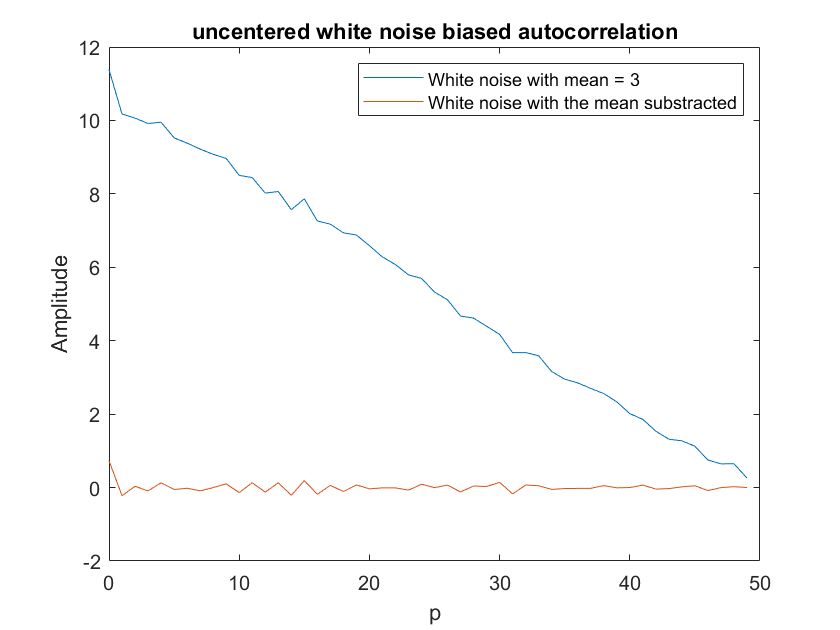

%plot continuation
hold on
plot(x_axis_p,BiasedCrossCorr(white_noise_unc - mean(white_noise_unc)))
legend("White noise with mean = "+white_noise_mean_unc, "White noise with the mean substracted")

### 3) Unbiased autocorrelation estimator

we created a funcion (inside its own script) to implement the unbiased autocorrelation estimator$^{2}$. 

Inputs:

- `X`: vector of signal samples

-  `pmax`: maximal amount of shift to be considered (optional, defaults to the length of X minus 1)

Outputs:

- `Cx`: vector of cross correlation samples for shifts varying from 0 to pmax

- `p`: vector of corresponding shifts

$^{2}$[As the previous one, we decided to not change the name of the function, but we think that the name is not the correct one. The title of the section is unbiased autocorrelation estimator, but the function is caled unbiased cross correlation, and only accepts one vector of signal samples].


$$\widehat{\gamma_{\mathrm{Xnb}} } \left(p,\omega \right)\frac{1}{N-p}\sum_{k=p}^{N-1} X\left(k,\omega \right){X\left(k,\omega \right)}^*$$


Test:

#### testing

Now we test this stimator against the real autocorrelation of the functions:

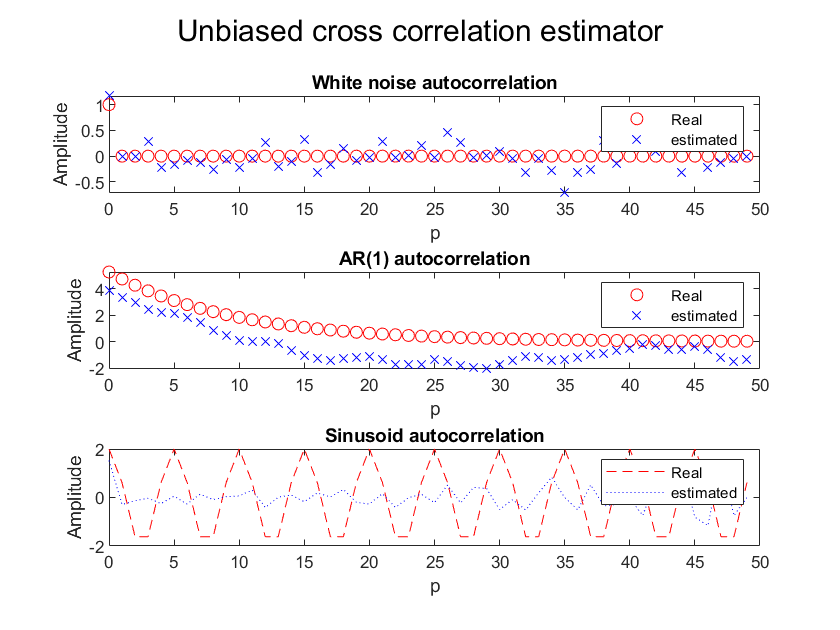

%plot
figure(4)
sgtitle("Unbiased cross correlation estimator")
est2_white_noise = UnbiasedCrossCorr(white_noise);
est2_AR1 = UnbiasedCrossCorr(AR1);
est2_sine = UnbiasedCrossCorr(sine);

subplot(3,1,1)
plot(x_axis_p,white_noise_autocorr,"ro")
hold on
plot(x_axis_p,est2_white_noise,"bx")
title("White noise autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

subplot(3,1,2)
plot(x_axis_p,AR1_autocorr,"ro")
hold on
plot(x_axis_p,est2_AR1,"bx")
title("AR(1) autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

subplot(3,1,3)
plot(x_axis_p,sine_autocorr,"r--")
hold on
plot(x_axis_p,est2_sine,"b:")
title("Sinusoid autocorrelation")
xlabel("p")
ylabel("Amplitude")
legend("Real","estimated")

Then, were are the questions and the answers:

- For random processes for which the theoretical autocorrelation is known, does the unbiased estimator converge when the number of samples grows? Do you actually observe a zero bias? 

N=50

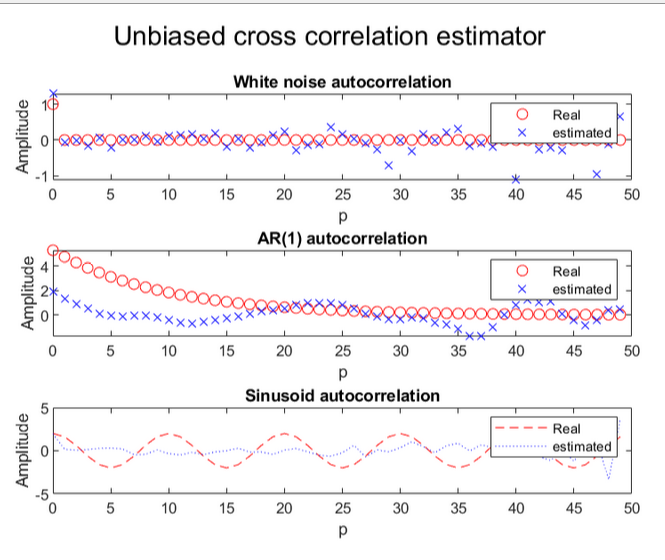

N=500 (first 50)

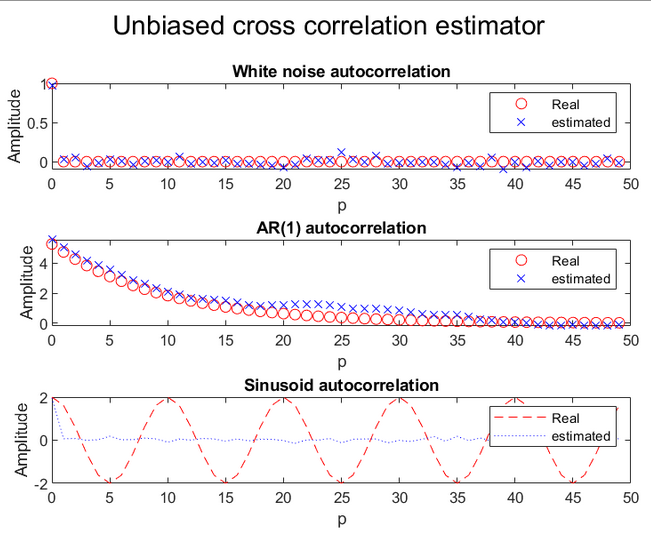

N=500

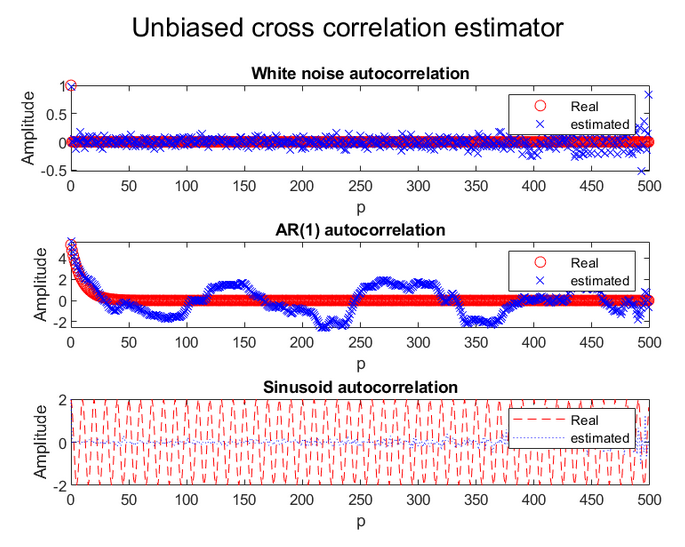

It seems to converge, but there is a problem of convergence at the last values of the shift. I do not observe a 0 bias, but it seems to have done something.

- Can you observe the effect of the variance of the estimator through certain examples? 

disp("    Estimation      |   Real  ")

    Estimation      |   Real  


disp("unbiased  | biased  | variance")

unbiased  | biased  | variance


disp("----------------------------")

----------------------------


disp(est2_white_noise(1) + "   | " + est_white_noise(1) + "  | " + var(white_noise))

1.1669   | 1.1669  | 1.1907


disp(est2_AR1(1) + "    | " + est_AR1(1) + "  | " + var(AR1))

3.8973    | 3.8973  | 3.937


disp(est2_sine(1) + "    | " + est_sine(1) + "  | " + var(sine))

1.5256    | 1.5256  | 1.5544


For our value of N (N=500 at the moment of answering), it seems that they are the same as in the unbiased ones. If we reduce N to 50, they are the same again, but they differ a considerable amount for the AR(1). If we reduce N to 10, they are the same again, but the error became bigger.

- Is the unbiased estimator more suitable for voiced or unvoiced sounds?

We would said voiced sounds, as we could see if we zoom that the sinusodial now have some meaningful pattern instead of something almost flat.

### 4) Establishing a criterion to determine the voiced / unvoiced type of sounds

1. The voiced sounds issued from speech present a fundamental frequency which varies between 100 Hz (man) and 400 Hz (child). Find the range of pseudo-periods that characterize voiced sounds. 

Here, doing a bit of basic algebra, we have a pseudoperiod of


$$T_1 =\frac{1}{400\mathrm{Hz}}=2\ldotp 5\mathrm{ms}\;\;\;;{\;\;T}_2 =\frac{1}{100\mathrm{Hz}}=10\mathrm{ms}$$


2. Perform a temporal observation of voiced sounds to measure their pseudo-period. 

Here we graph the voiced signals to see the pseudoperiod

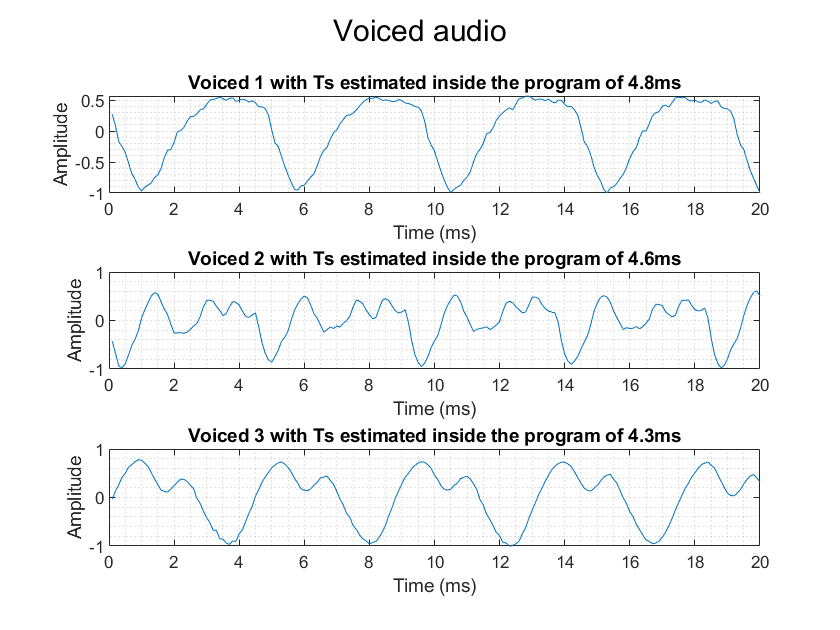

%plot
figure(5)
number_of_samples = 200;
x_axis_t = Ts.*(1:1024).*1000;

subplot(3,1,1)
sgtitle("Voiced audio")

voiced1 = voiced_audios(1,:);
Min_prom = (max(voiced1) - min(voiced1))/2;
[~, peak_index_1] = findpeaks(voiced1,"MinPeakProminence",Min_prom);
est_Tsignal_1 = x_axis_t(peak_index_1(2)) - x_axis_t(peak_index_1(1));

plot(x_axis_t(1:number_of_samples), voiced1(1:number_of_samples))
title("Voiced 1 with Ts estimated inside the program of " + est_Tsignal_1 + "ms")
grid minor
xlabel("Time (ms)")
ylabel("Amplitude")

subplot(3,1,2)

voiced2 = voiced_audios(2,:);
Min_prom = (max(voiced2) - min(voiced2))/2;
[~, peak_index_2] = findpeaks(voiced2,"MinPeakProminence",Min_prom);
est_Tsignal_2 = x_axis_t(peak_index_2(2)) - x_axis_t(peak_index_2(1));

plot(x_axis_t(1:number_of_samples), voiced2(1:number_of_samples))
title("Voiced 2 with Ts estimated inside the program of " + est_Tsignal_2 + "ms")
grid minor
xlabel("Time (ms)")
ylabel("Amplitude")

subplot(3,1,3)

voiced3 = voiced_audios(3,:);
Min_prom = (max(voiced3) - min(voiced3))/2;
[~, peak_index_3] = findpeaks(voiced3,"MinPeakProminence",Min_prom);
est_Tsignal_3 = x_axis_t(peak_index_3(2)) - x_axis_t(peak_index_3(1));

plot(x_axis_t(1:number_of_samples), voiced3(1:number_of_samples))
title("Voiced 3 with Ts estimated inside the program of " + est_Tsignal_3 + "ms")
grid minor
xlabel("Time (ms)")
ylabel("Amplitude")

If we measure normaly, we estimate a pseudoperiod of 4.75ms, 4.6ms and 4.3ms respectively.

3. Check that you can recover the same pseudo-periods from the estimated autocorrelations. 

Now, we do the same but with the autocorrelations

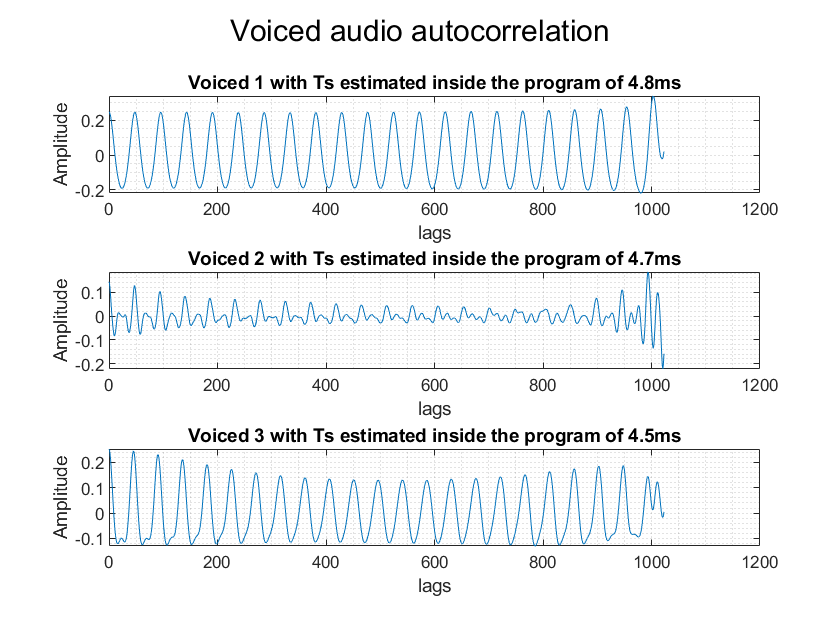

%plot
figure(6)
number_of_samples = 1024;
start_of_signal = 2;
x_axis_p = 0:1023;

subplot(3,1,1)
sgtitle("Voiced audio autocorrelation")

voiced1 = UnbiasedCrossCorr(voiced_audios(1,:));

Min_prominence = (max(voiced1) - min(voiced1))/2;
[~, peak_index_1] = findpeaks(voiced1(start_of_signal:number_of_samples),...
                               "MinPeakProminence",Min_prominence...
                               );
est_Tsignal_1 = (peak_index_1(1) + start_of_signal-2) .* Ts *1000;

plot(x_axis_p(1:number_of_samples), voiced1(1:number_of_samples))
title("Voiced 1 with Ts estimated inside the program of " + est_Tsignal_1 + "ms")
grid minor
xlabel("lags")
ylabel("Amplitude")

subplot(3,1,2)

voiced2 = UnbiasedCrossCorr(voiced_audios(2,:));

Min_prominence = (max(voiced2) - min(voiced2))/2;
[~, peak_index_2] = findpeaks(voiced2(start_of_signal:number_of_samples),...
                               "MinPeakProminence",Min_prominence...
                               );
est_Tsignal_2 = (peak_index_2(1) + start_of_signal-2) .* Ts *1000;

plot(x_axis_p(1:number_of_samples), voiced2(1:number_of_samples))
title("Voiced 2 with Ts estimated inside the program of " + est_Tsignal_2 + "ms")
grid minor
xlabel("lags")
ylabel("Amplitude")

subplot(3,1,3)

voiced3 = UnbiasedCrossCorr(voiced_audios(3,:));

Min_prominence = (max(voiced3) - min(voiced3))/2;
[~, peak_index_3] = findpeaks(voiced3(start_of_signal:number_of_samples),...
                               "MinPeakProminence",Min_prominence...
                               );
est_Tsignal_3 = (peak_index_3(1) + start_of_signal-2) .* Ts *1000;

plot(x_axis_p(1:number_of_samples), voiced3(1:number_of_samples))
title("Voiced 3 with Ts estimated inside the program of " + est_Tsignal_3 + "ms")
grid minor
xlabel("lags")
ylabel("Amplitude")

If we measure normally, we find a pseudoperiod of 4.8ms, 4.7ms, and 4.5ms respectively. (This was measured wtih the plot, not with the program, we especify)

4. Observe how the “structure” of unvoiced signals makes the autocorrelation decrease when the shift increases. 5. Propose a criterion to distinguish voiced sounds from unvoiced sounds and implement it

First we plot the signals to see the phenomena

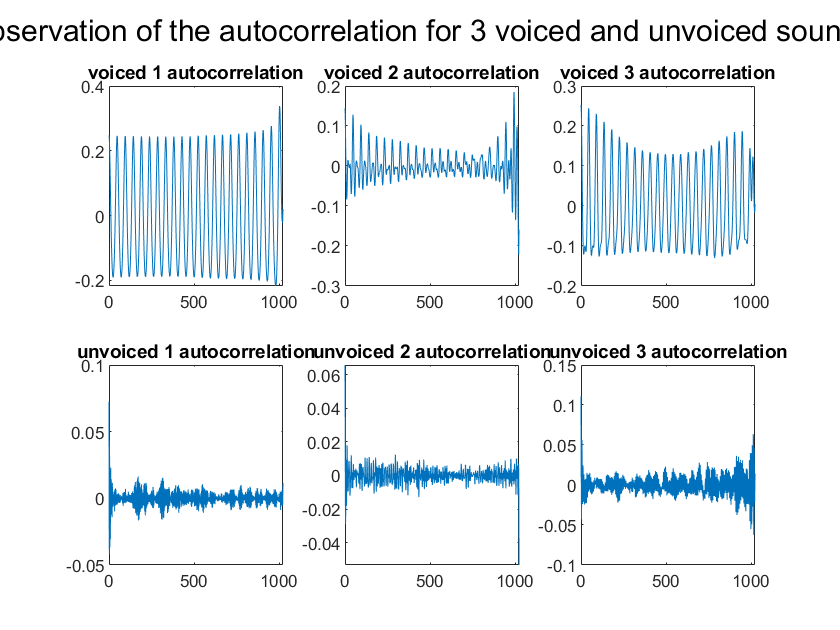

figure(7)
subplot(2,3,1)
sgtitle("Observation of the autocorrelation for 3 voiced and unvoiced sounds")
Y = UnbiasedCrossCorr(voiced_audios(1,:));
plot(x_axis_p,Y);
title("voiced 1 autocorrelation")

subplot(2,3,2)
Y = UnbiasedCrossCorr(voiced_audios(2,:));
plot(x_axis_p,Y);
title("voiced 2 autocorrelation")

subplot(2,3,3)
Y = UnbiasedCrossCorr(voiced_audios(3,:));
plot(x_axis_p,Y);
title("voiced 3 autocorrelation")

subplot(2,3,4)
Y = UnbiasedCrossCorr(unvoiced_audios(1,:));
plot(x_axis_p,Y);
title("unvoiced 1 autocorrelation")

subplot(2,3,5)
Y = UnbiasedCrossCorr(unvoiced_audios(2,:));
plot(x_axis_p,Y);
title("unvoiced 2 autocorrelation")

subplot(2,3,6)
Y = UnbiasedCrossCorr(unvoiced_audios(3,:));
plot(x_axis_p,Y);
title("unvoiced 3 autocorrelation")

After looking at them, voiced sounds have some sort of big values compared to the unvoiced ones in the midle, and the values of unvoiced ones are really smal when they are not in the lower p's. One way we could detect if iis voiced or not could be to use a threshold that depends on the variance and the values of the peaks. Here we created a function for that:

**Inputs:**

- `Cx`: vector of cross correlation samples for shifts varying from 0 to numel(Cx)-1.

**Outputs:**

- bool:  1 (true) if the sound is voiced, 0 (false) otherwise. 

Then we test it

%there could be plots if it gets uncommented in the function
%so we will be doing the count of the figures like it plotted
disp("Type     | predicted ")

Type     | predicted 


disp("---------------------")

---------------------


for i=1:3
    disp("voiced   | "+ isVoiced(UnbiasedCrossCorr(voiced_audios(i,:))))
end

voiced   | true
voiced   | true
voiced   | true


for i=1:4
    disp("unvoiced | "+ isVoiced(UnbiasedCrossCorr(unvoiced_audios(i,:))))
end

unvoiced | false
unvoiced | false
unvoiced | false
unvoiced | false


## S2 Spectral analysis 

### 1) Sample data

As in the previous session, you can begin by testing your estimators using realizations of random processes for which you know the spectral features: white noise, AR1, and especially random phase sine waves. After these tests, you can go further and analyse the spectral features of voiced and unvoiced sounds in the repository provided.

We already tested our stimators, but it is not good on sinusoids as expected.

### 2)  Two approaches for (almost . . . ) the same estimator

In order to estimate the power spectral density (PSD) of a random process X whose trajectory has been observed over a finite number N of samples, there are two possible approaches:

-  -correlogram: use the biased autocorrelation estimator and compute its Fourier transform,

-   periodogram: compute the discrete-time Fourier transform (DTFT) of the available samples, take its squared modulus and divide by the number of samples. 

In practice, it is not possible to estimate the power spectral density for all possible values of reduced frequency (the variable is continuous). We will thus compute the PSD over a finite set of reduced frequencies. You can exploit the FFT algorithm to compute discrete Fourier transforms, with a suitable choice of the parameter $N_{\mathrm{fft}}$.

Write a function which implements the estimation of the PSD as described below: 

**Inputs:**

- X: vector of signal samples

- Nfft: Number of signal samples to be considered in the discrete Fourier transform (see FFT) (optional argument, defaults to twice the length of X)

**Outputs:**

- PSD: vector of PSD estimates for normalized frequency varying from 0 to 1/2.

-  nu: vector of corresponding normalized frequency values.

We created the funcion in another script.

Then we tested it with our signals

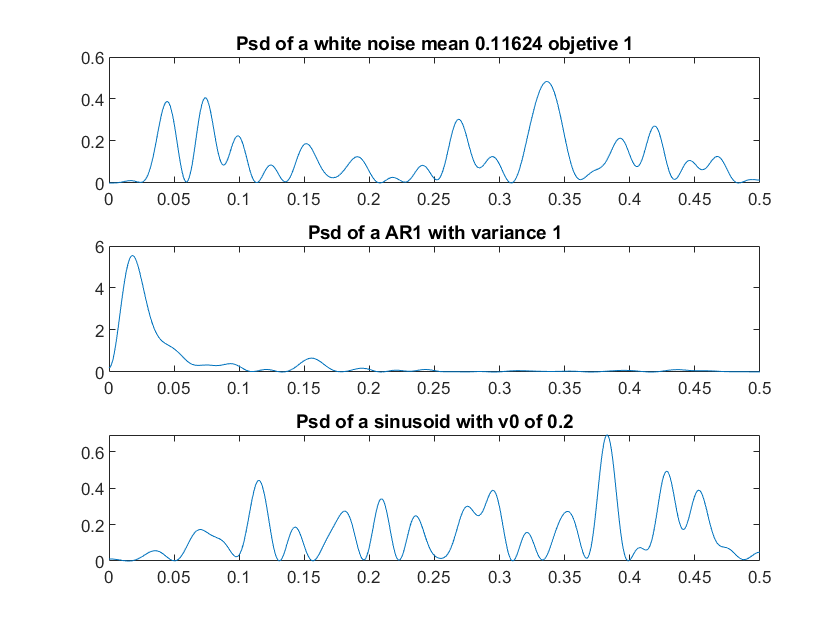

figure(8)
Nfft = 1000;

subplot(3,1,1)
[y,x] = psdEstimator(white_noise,Nfft);
plot(x,y)
title("Psd of a white noise mean "+ mean(y) + " objetive " + white_noise_variance)

subplot(3,1,2)
[y,x] = psdEstimator(AR1,Nfft);
plot(x,y)
title("Psd of a AR1 with variance " + AR1_variance)

subplot(3,1,3)
[y,x] = psdEstimator(sine,Nfft);
plot(x,y)
title("Psd of a sinusoid with v0 of "+ sine_reduced_frequency)

then, we answer the questions:

- What is the minimum value of Nfft such that the values returned by the FFT algorithm correspond to the expected discrete Fourier transform?

Nfft have to be two times the length of the signal.

- For the correlogram method, which values should you take for the shift? 

for all the shifts from 0 to the length of the signal segment we want to analize

- For the correlogram method, can you write the vector of the autocorrelation coeficients in such a way that the coeficients computed using the FFT are purely real (and positive)?

[To do later]

- For the periodogram method, which number of samples should you use to renormalize the results? N or Nfft? 

Nfft, as we know work with the frequency.

- What are the reduced frequencies corresponding to the coeficients returned by the FFT algorithm? 

it returns the reduced frequencies form 0 to 1

- How to get only the spectral samples corresponding to a reduced frequency between 0 and 1/2? 

Cutting the output samples so it correspond to the ones from 0 to 0.5

- Test your function with the realizations of a sine wave with random phase whose frequency ν0 is an irrational number (for example ν0 = √ 2/8). 

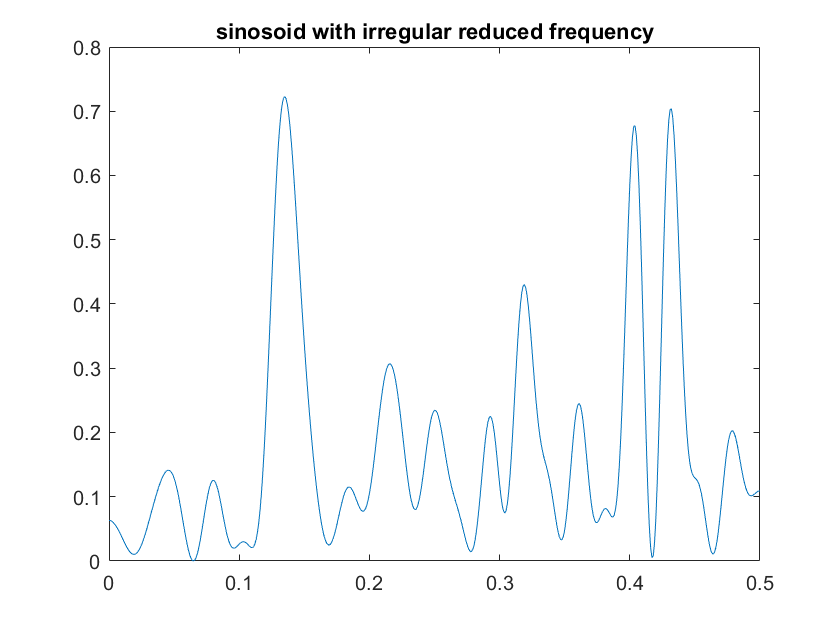

sine_reduced_frequency_irr = sqrt(2)/8;
sine_angules_irr = 2.*pi.*sine_reduced_frequency_irr.*(1:N);

sine_irr = sine_amplitude.*sin(sine_angules_irr + sine_phase_shifts);
figure(15)
[y,x] = psdEstimator(sine_irr,Nfft);
plot(x,y)
title("sinosoid with irregular reduced frequency")

Here we see that we do not have the specific value (With the constans we selected at the moment), but we have values near that.

- Test the resolution capability of your estimator for the superposition of two sine waves whose frequences ν1 and ν2 are very close.

We have a resolution of 0.001 aproximately (With the constans we selected at the moment)

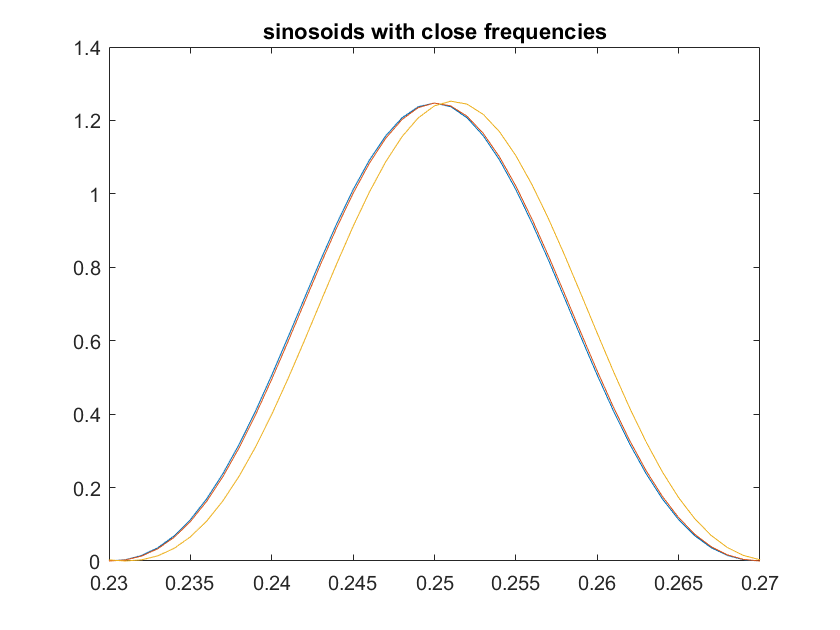

figure(16)
[y1,x1] = psdEstimator(sin(2.*pi.*0.25.*(1:N)),Nfft);
[y2,x2] = psdEstimator(sin(2.*pi.*0.2501.*(1:N)),Nfft);
[y3,x3] = psdEstimator(sin(2.*pi.*0.251.*(1:N)),Nfft);

plot(x1,y1,x2,y2,x3,y3)
title("sinosoids with close frequencies")
xlim([0.23 0.27])

Here we can see that the peak is in the same place for both, althought it is sightly different and one that has a change that can be seen with our resolution. (selected artifically) 

### 3) 

### Reliability of spectral estimation

Here we modificated the function so it accepts more arguments as options, and if we have a third one, we do that in blocks and test it with the funcions we used before with a K value of 8

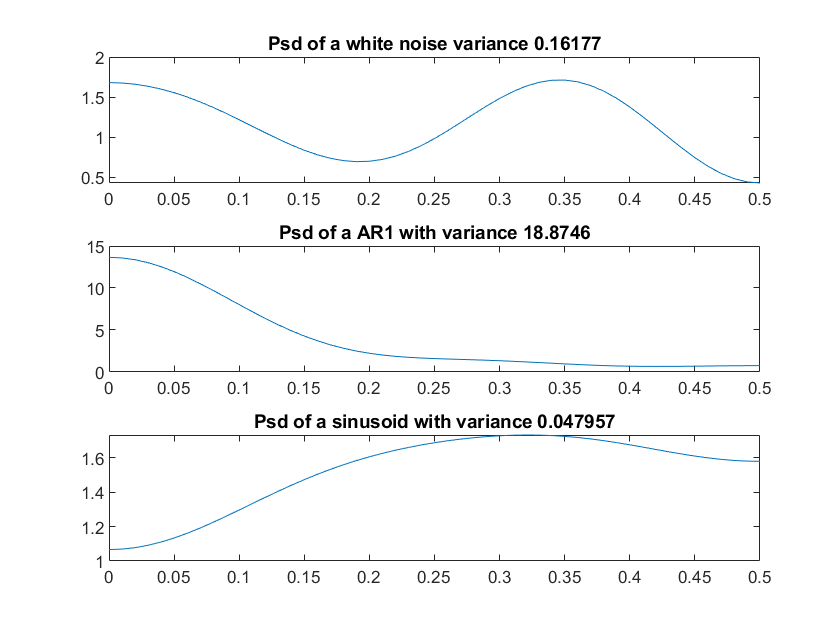

figure(17)
K = 10;

subplot(3,1,1)
[y,x] = psdEstimator(white_noise,Nfft,K);
plot(x,y)
title("Psd of a white noise variance "+ var(y))

subplot(3,1,2)
[y,x] = psdEstimator(AR1,Nfft,K);
plot(x,y)
title("Psd of a AR1 with variance " + var(y))

subplot(3,1,3)
[y,x] = psdEstimator(sine,Nfft,K);
plot(x,y)
title("Psd of a sinusoid with variance " + var(y))

Then we answer the questions

- How does the variance of the estimate of the PSD of a white noise scale with respect to the number of samples N? Does your observation match the theory?

[To do later]

- How does the variance of the estimate of the PSD of an AR1 process scale with respect to the number of samples N? Does your observation match the theory?

- How does the variance of the estimate of the PSD of a random phase sine wave scale with respect to the number of samples N? Does your observation match the theory?

- Can you improve the variance of the estimator by averaging? If so, what is the price to pay?

Yes, but then our estimation starts to get broken at K too near to N. Example: when we have N=500 and K=100, the white noise is like a parabola. We can not see any specific thing about it. We sacrified the frequency we can see.

### 4) Choice of a time window

In accordance with the spectral nature of the observed signal, one might want to weight the

available samples using different windows.

Non-exhaustive list of questions you can consider:

- What type of plot is more suitable to represent the PSD of a process presenting spectral lines?

flat top, as we do not have lots of spikes and we do not expect some similar power in them.

- Which type of window should you choose to analyse the spectrum of a signal with very little structure?

Hann, as it is like a ranom process

- How to renormalize the window coeficients in such a way that for a white noise signal you can recover the noise variance from the PSD estimate?

we can calcualte the effect of the window and then divide by the factor it multiplies.

- Which window should you choose when you want to estimate precisely the fundamental frequency of a voiced sound?

Rectangular window, as the frequency is important

- Which window should you choose when you want to estimate the amplitude of the harmonic composing a voiced sound? How to renormalize the window coeficients so that the corresponding peak height gives directly the amplitude?

Rectangular, as the voiced sounds could be modeled as sinusoids, then we want the frequency and we have a single, or 2 spikes with similar power. We can measure the window and then multiply by a constant that mitigates the effect on the PSD.

- How does the variance of the estimate of the PSD of an AR1 process scale with the number of samples N? Does your observation match the theory?

- How does the variance of the estimate of the PSD of a random phase sine wave scale with the number of samples N? Does your observation match the theory?

- Can you establish a reliable criterion based on the PSD estimator to distinguish between voiced and unvoiced sounds? If so, how does it compare to the criterion based on the autocorrelation?

## S3: Linear prediction

### 1) Solving the Yule-Walker equations

We created a function to solve the Yule-Walker ecuations:

**Inputs:**

- Cx: Cross-correlation vector for lags 0 to K

- K: order ( optional argument, defaults to length(Cx) -1 )

**Outputs:**

- a: vector of filter coefficients.

- v: prediction of error variance or innovation power

- coeff: Extra argument that directly gets the quality of modeling

Then we tested it with the AR(1) theorical autocorrelation (white noise variance = 1, a = 0.7)

x_axis_p = 0:N-1;

AR1_teo = (0.7 .^ x_axis_p)./(1-0.7.^2);
[aopt,v_e] = YuleWalkerSolver(AR1_teo,1);
disp("a_opt: " + string(aopt))

a_opt: 0.7


disp("variance inovation: " + string(v_e))

variance inovation: 1


it acted as expected. We have the same values for the coefficient and the inovation variance.

Now with a teoretical AR4. We created a function that takes as input: N as the lenght, K as the order, and variance as the noise variance.

The outputs are in order. The signal, the coefficients, the autocorrelation from 0 to N-1, and the shifts p.

This finction was created in order to facilitate the work with the AR(K) signals.

[~, a4, AR4_teo] = ARK_gen(N,4,1);
disp(["a_real: " string(a4)])

    "a_real: "    "-0.9855"    "-0.90352"    "-0.030307"    "-0.41857"




figure(18)
[aopt,v_e] = YuleWalkerSolver(AR4_teo,4)

aopt =     0.6288
   -0.0430
    0.3277
   -0.0960


v_e = 1.6193

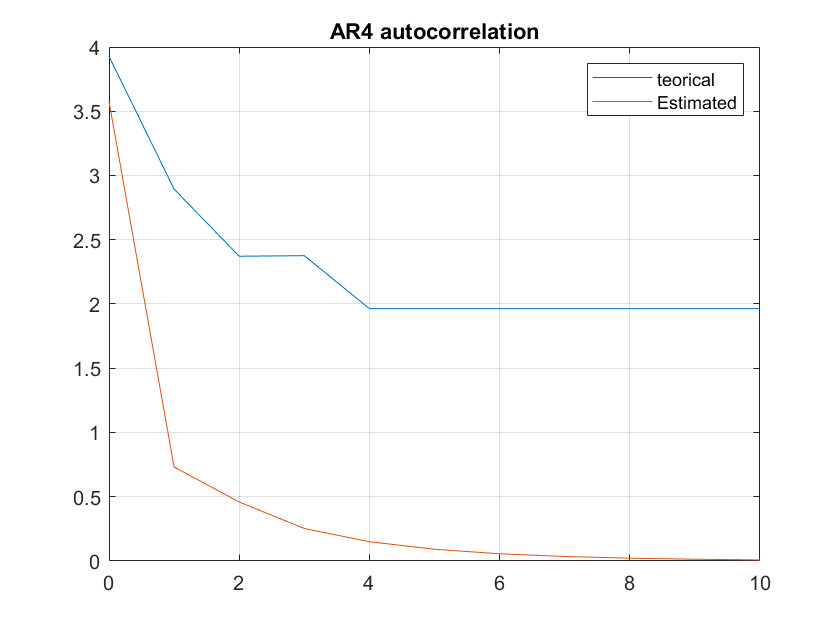

AR4_opt = (aopt(1).^x_axis_p + aopt(2).^x_axis_p + aopt(3).^x_axis_p + aopt(4).^x_axis_p)./(1 + aopt(2).^2 + aopt(3).^2 + aopt(4).^2);
plot(x_axis_p,AR4_teo,x_axis_p,AR4_opt);
title("AR4 autocorrelation")
legend(["teorical" "Estimated"])
xlim([0,10])
grid on

It does not look ok. There will be always error with this AR signal. But at the end they look really similar.

There is a problem here that the estimated signal grows exponentialy sometimes. We think that it estimates an unstable filter in that cases.

When that does not happens, we have that the estimated signal will be lower than the teorical.

Then, we anser the questions

- What should the YuleWalkerSolver function do if the input vector Cx contains less than K + 1 elements? 

It should estimate the coefficients for a filter of an AR(N-1) instead of an AR(K). This is something we would want, so if we have a really long signal, but can be described by an AR(K) filter with a small K value, we could estimate for that value.

- Which random process with known autocorrelation can you use to test the function at the order K = 1? Which optimal coeficients do you expect to obtain? 

The AR(1) expecting the same coefficients as the filter. The AR(1) signal is not a complex signal so it have to really looks for something similar, bit we only have to find one variable that will be always the same as the real one, or it would not be optimal.

- Which random process with known autocorrelation can you use to test the function at the order K = 2? Which optimal coeficients do you expect to obtain?

we do not expect the exact same coefficients, but someones that gives a signal that goes lower than the teorical, but looks similar.

 - How can you test the correctness of the function for higher orders K? 

In the function of the yule Walker ecuations, we have an output of the error variance. We are going to test with an AR(4) and a we are going to iterate from K in the range [1:50] and graph that.

[~, ~, AR4_teo] = ARK_gen(1024,4,1)

AR4_teo =     1.8201    0.8891    1.0009    1.0198    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100    0.9100


maxK = 50

maxK = 50

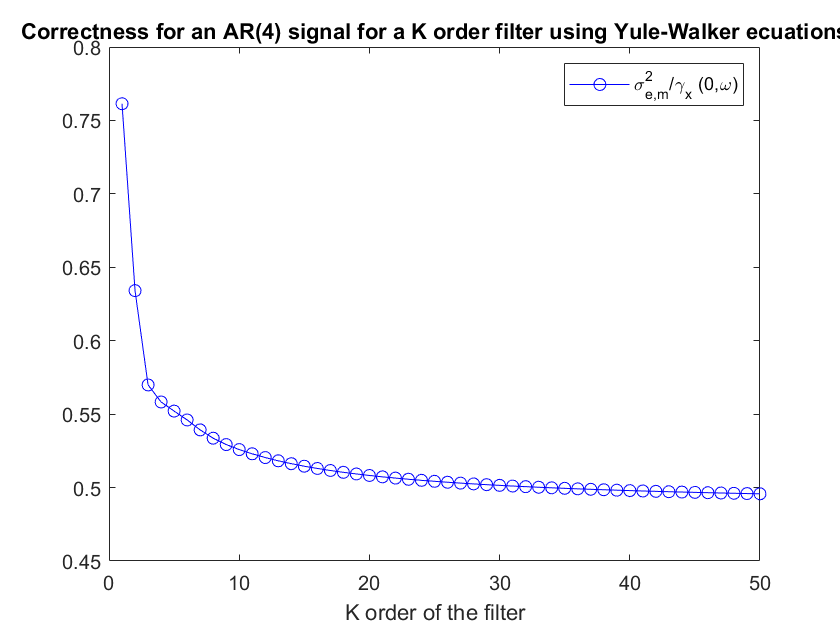


correctness = zeros(1,maxK);
for i=1:maxK
    [~,~,correctness(i)] = YuleWalkerSolver(AR4_teo,i);
end

figure(19)
plot(1:maxK,correctness,"b-o")
title("Correctness for an AR(4) signal for a K order filter using Yule-Walker ecuations")
xlabel("K order of the filter")
legend("{\sigma^2_{e,m}}/{\gamma_x (0,\omega)}")

Here we can see it gets to a value different than 0 when $K\to \infty$

This is expected as there is always a constant error between the estimated signal and the real one, so it can not get to 0.

- What happens for an AR(1) and K > 1? - What happens for a random phase sine wave and K > 2?

AR1_teo = (0.7 .^ x_axis_p)./(1-0.7.^2);
[aopt,~] = YuleWalkerSolver(AR1_teo,4);
disp("a: 0.7 | aopt : ")

a: 0.7 | aopt : 


disp(aopt)

    0.7000
    0.0000
         0
         0



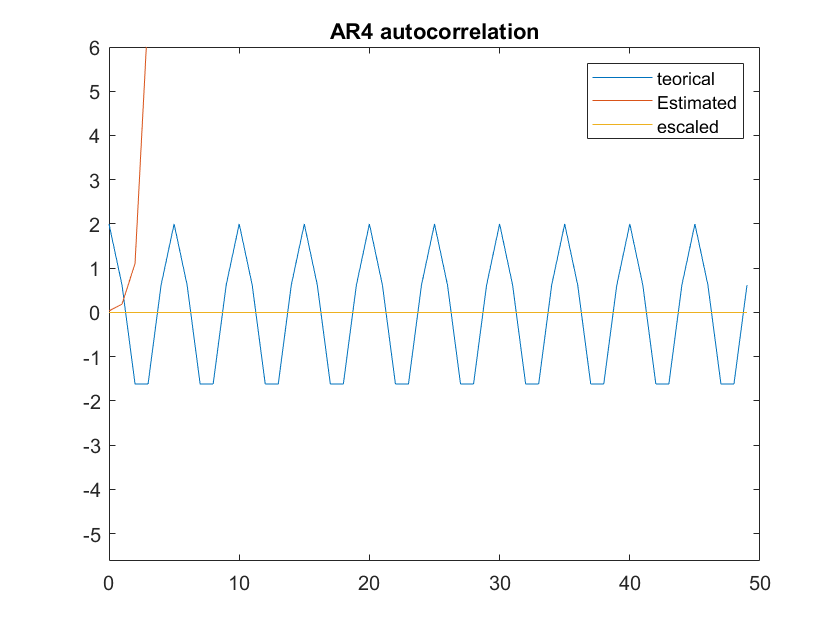


[aopt,~] = YuleWalkerSolver(sine,4);
figure(20)


AR4_opt = (aopt(1).^x_axis_p + aopt(2).^x_axis_p + aopt(3).^x_axis_p + aopt(4).^x_axis_p)./(1 + aopt(2).^2 + aopt(3).^2 + aopt(4).^2);
plot(x_axis_p,sine_autocorr,x_axis_p,AR4_opt,x_axis_p,AR4_opt.*10.^-80);

title("AR4 autocorrelation")
legend(["teorical" "Estimated" "escaled"])
ylim([min(sine_autocorr)-4 max(sine_autocorr)+4])

for the AR(1), it gives us an AR(1) too, but with the sinusoid, it gives us really big values compared to the real one. I can not define a sine wave in tthat values, and it gets bigger with p.

### 2) Realizations of known random processes

Here we does the process again, but with the biased estimator:

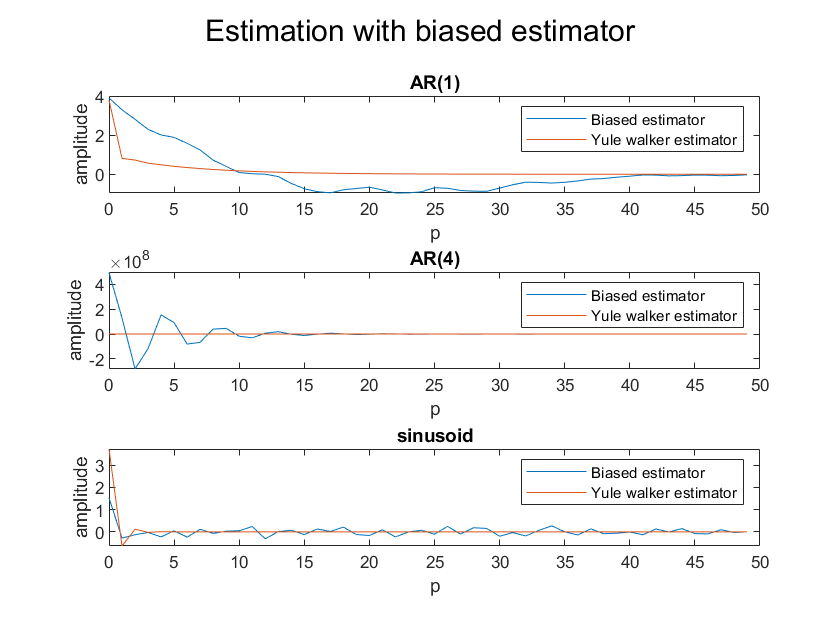

signal1 = BiasedCrossCorr(AR1);
[signal2, a4] = ARK_gen(N,4,1);
signal2 = BiasedCrossCorr(signal2);
signal3 = BiasedCrossCorr(sine);

[aopt1,var1] = YuleWalkerSolver(signal1,4);
[aopt2,var2] = YuleWalkerSolver(signal2,4);
[aopt3,var3] = YuleWalkerSolver(signal3,4);

AR4_opt1 = (aopt1(1).^x_axis_p + aopt1(2).^x_axis_p + aopt1(3).^x_axis_p + aopt1(4).^x_axis_p)./(1 + aopt1(2).^2 + aopt1(3).^2 + aopt1(4).^2);
AR4_opt2 = (aopt2(1).^x_axis_p + aopt2(2).^x_axis_p + aopt2(3).^x_axis_p + aopt2(4).^x_axis_p)./(1 + aopt2(2).^2 + aopt2(3).^2 + aopt2(4).^2);
AR4_opt3 = (aopt3(1).^x_axis_p + aopt3(2).^x_axis_p + aopt3(3).^x_axis_p + aopt3(4).^x_axis_p)./(1 + aopt3(2).^2 + aopt3(3).^2 + aopt3(4).^2);

figure(21)
subplot(3,1,1)
sgtitle("Estimation with biased estimator")
plot(x_axis_p, signal1, x_axis_p, AR4_opt1)
title("AR(1)")
xlabel("p")
ylabel("amplitude")
legend(["Biased estimator" "Yule walker estimator"])

subplot(3,1,2)
plot(x_axis_p, signal2, x_axis_p, AR4_opt2)
title("AR(4)")
xlabel("p")
ylabel("amplitude")
legend(["Biased estimator" "Yule walker estimator"])

subplot(3,1,3)
plot(x_axis_p, signal3, x_axis_p, AR4_opt3)
title("sinusoid")
xlabel("p")
ylabel("amplitude")
legend(["Biased estimator" "Yule walker estimator"])

Then, we answer the questions.

Non-exhaustive list of questions you can consider:

- How does the variance of the prediction error depend on the order K? For a given process, how do you choose K?

It depends as the variance of the prediction error is equal to the multiplication of the covariance matrix and the optimal parameters. So if we change the dimensions of the matrix, and therefore the values of the optimal parameters, and we add some to the covariance matrix, we change the value of the error variance.

We choose a K value that gives us the smallest value with the smaller K possible.

- How does the prediction compare to a given realization? How does the prediction error compare to a given realization? What is the behavior of the autocorrelation of the prediction error as a function of the shift p? Which process can you use to model this error? How does the autocorrelation of the prediction error compare to the autocorrelation of the signal?

Here we plot the autocorrelation of the signal, the estimateed signal, and the prediction error for an AR(1) signal, estimateed by an AR(4) filter,

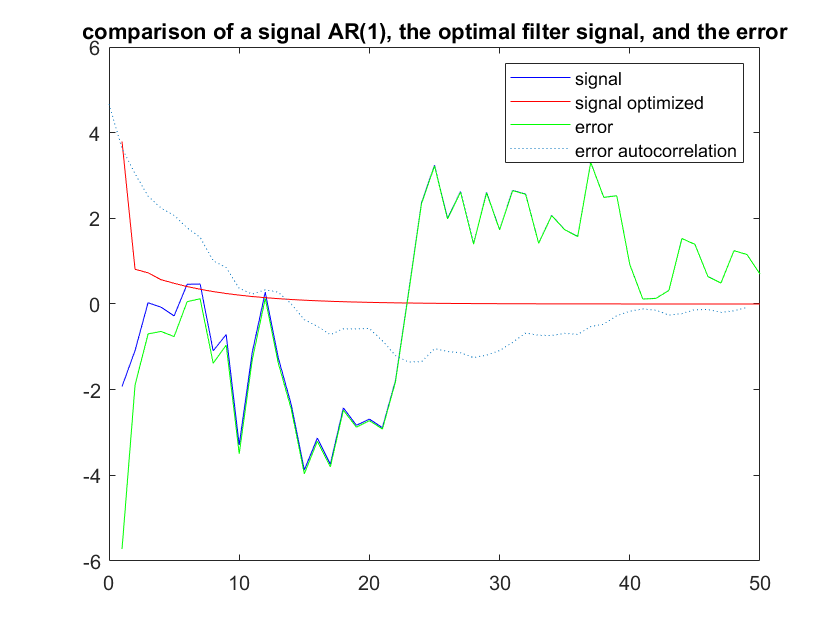

figure(22)
%Here we found the error
errorFilter = AR1-AR4_opt1;
%we find the estimated autocorrelation
[yp,xp] = BiasedCrossCorr(errorFilter);
%and plot the different signals
plot(x_axis_n,AR1,"b",x_axis_n,AR4_opt1,"r",x_axis_n,errorFilter,"g", xp, yp, ":")
title("comparison of a signal AR(1), the optimal filter signal, and the error")
legend(["signal" "signal optimized" "error" "error autocorrelation"])

The prediction is not the same as the realization. The predicted value looks really constant and smooth compared to the signal. the prediction error looks like oscilationg between being higher and lower, like an AR process. This error is almost identical to the signal itself. The prediction error autocorrelation looks like it gets lower at higher shifts, as expected because it looks like an AR process.

The error is really different at the begining, but later, as the signal of the optimized filter gets to zero, the error gets equeal to the signal.

- When modeling the signal by an AR(K) process defined by the parameters provided by linear prediction, what is the behavior of the estimated PSD? To what extent does it match the theoretical DSP?

we continue with the data from the last question.

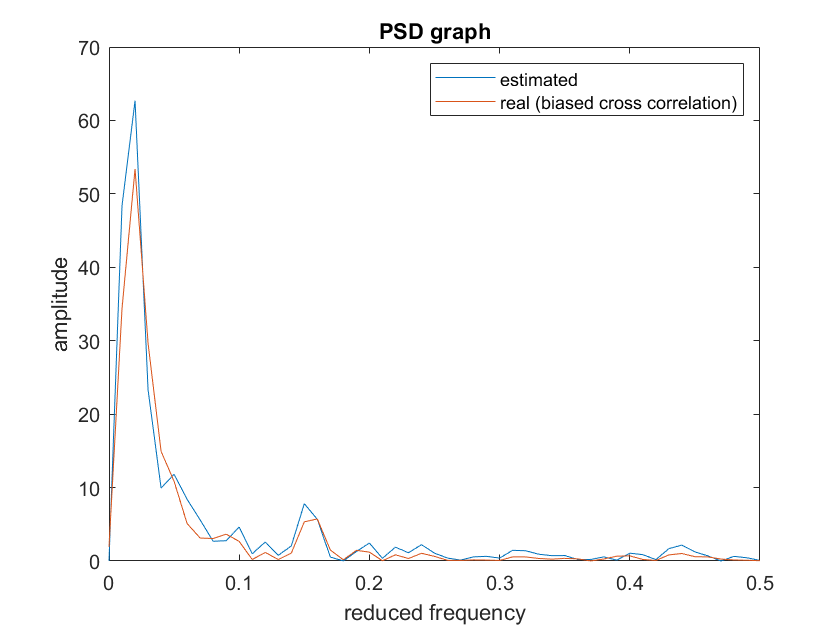

[testPSD1, x_axis_v0] = psdEstimator(errorFilter);
[testPSD2, ~] = psdEstimator(AR1);
figure(23)
plot(x_axis_v0,testPSD1,x_axis_v0,testPSD2);
title("PSD graph")
xlabel("reduced frequency")
ylabel("amplitude")
legend(["estimated" "real (biased cross correlation)"])

It matchs the estimated PSD, well enought. It looks like it is correct.

### 3) Voiced and unvoiced sounds

Now we do this with the voiced and unvoiced sounds, asnwering the questions

%Here we prepare the data
voiced_corr = zeros(3,1024);
unvoiced_corr = zeros(4,1024);
x_axis_p = 0:1023;

%This is the max value of K we are going to take information
K_max = 20;

%We get the estimated biased autocorrelation of the signals
for i=1:3
    voiced_corr(i,:) = BiasedCrossCorr(voiced_audios(i,:));
end
for i=1:4
    unvoiced_corr(i,:) = BiasedCrossCorr(unvoiced_audios(i,:));
end

%Then, we get the error variance divided by the autocorrelation when P=0 of
%the signal
voiced_error_variance = zeros(3,K_max);
unvoiced_error_variance = zeros(4,K_max);
for j=1:K_max
    for i=1:3
        [~,~,voiced_error_variance(i,j)] = YuleWalkerSolver(voiced_corr(i,:),j);
    end
    for i=1:4
        [~,~,unvoiced_error_variance(i,j)] = YuleWalkerSolver(unvoiced_corr(i,:),j);
    end
end

- Which order K is it reasonable to choose when performing linear prediction for voiced sounds? And for unvoiced sounds?

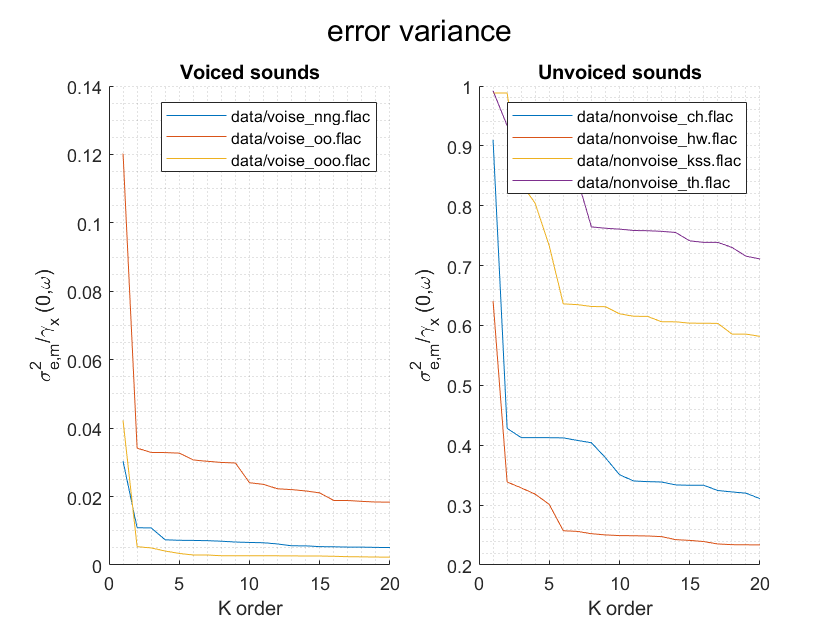

figure(24)
subplot(1,2,1)
sgtitle("error variance")
hold on
%Here we plot the error variances calculated form before
for i = 1:3
    plot(1:K_max,voiced_error_variance(i,:))
end
title("Voiced sounds")
legend(voiced_names, "Interpreter","none")
xlabel("K order")
ylabel("{\sigma^2_{e,m}}/{\gamma_x (0,\omega)}")
grid minor

subplot(1,2,2)
hold on
for i = 1:4
    plot(1:K_max,unvoiced_error_variance(i,:))
end
title("Unvoiced sounds")
legend(unvoiced_names, "Interpreter","none")
xlabel("K order")
ylabel("{\sigma^2_{e,m}}/{\gamma_x (0,\omega)}")
grid minor

So, after graphing, we decided that the best K for voiced sounds is 2, and for unvoiced sounds is 10. We decided this values as the constant we use it is already low, and after that popint the changes are minimun.

- Depending on the voiced or unvoiced nature of the signal, what is the behavior of the autocorrelation of the prediction error as a function of the shift p? What random process can you use to model these errors?

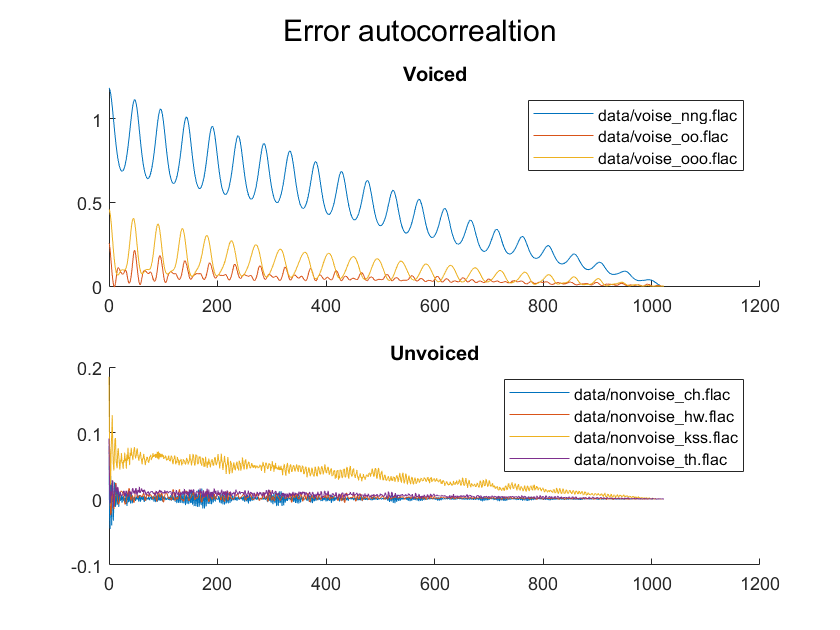

figure(25)
subplot(2,1,1)
sgtitle("Error autocorrealtion")
hold on
ordervoice = 2;
orderunvoice = 10;
for i=1:3
    %read the audio and estimate the autocorrelation
    aud = voiced_audios(i,:);
    autocorr = BiasedCrossCorr(aud);
    
    %get the optimal parameters of an AR filter and the variance of the
    %error with the Yule-Walker ecuations
    [predicteda, predictedv] = YuleWalkerSolver(autocorr, ordervoice);
    %Then, we create the filter with that especifications and susbtract
    %that from the real audio signal to get the error
    predicted = filter(1, [1 -predicteda'], sqrt(predictedv).*rand(1,1024));
    predicted = aud - predicted;
    %then, we estimate the autocorrelation of the error and plot it
    [errorAutocorr, xp] = BiasedCrossCorr(predicted);
    plot(xp,errorAutocorr)
end
title("Voiced")
legend(string(voiced_names), "Interpreter","none")
subplot(2,1,2)
hold on
for i=1:4
    %We repeat the same for the unvoiced ones
    aud = unvoiced_audios(i,:);
    autocorr = BiasedCrossCorr(aud);
    [predicteda, predictedv] = YuleWalkerSolver(autocorr, orderunvoice);
    predicted = filter(1, [1 -predicteda'], sqrt(predictedv).*rand(1,1024));
    predicted = aud - predicted;
    [errorAutocorr, xp] = BiasedCrossCorr(predicted);
    plot(xp,errorAutocorr)
end
title("Unvoiced")
legend(string(unvoiced_names), "Interpreter","none")

For the voiced ones, it looks like a sinusoid, but the values decrease with P. For the unvoiced, it looks like white noise, with a very low variance in this case. It could not be an AR because it have negative values. The values are only signifiant

Some of them are not centered, so we see that they go in a diagonal instead of a line in the X axis.

- How do the parametric spectral estimators developed here compare to the non-parametric estimators that you have implemented in the previous session? 

## S4: Coding, decoding and voice effects

### 1) Analysis of a block

We wrote a function to analyse a block of 256 signal samples, described as follows :

**Inputs:**

- X: vector of samples of the current block of signal

- M:  filter order (optional, defaults to 10)

- Fe: sampling frequency (optional, defaults to 10kHz)

**Outputs:**

- pitch: the pitch value in normalized frequency if the sound is voiced, -1 otherwise

- sigma2: the variance of excitation

- Aopt: vector of filter coefficients (optimal linear prediction of order M)

And inside that we used another fuction called pitchDetector to detect the pitch, described with:

**Inputs:**

- Cx: vector of cross-correlation samples for shifts varying from 0 to pmax.

- Fe: sampling frequency (optional, defaults to 10kHz).

- Fmin: minimal pitch (optional, defaults to 100Hz) 

- Fmax: maximal pitch (optional, defaults to 400Hz) 

**Outputs:**

- pitch: the pitch value in normalized frequency if the sound is voiced, -1 otherwise

We are following this diagram for the block:

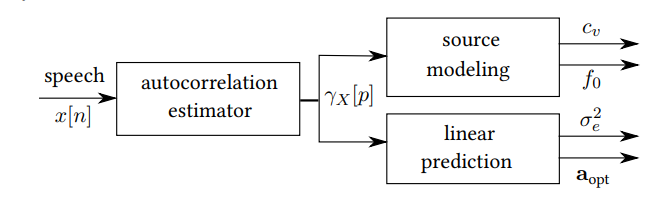

### 2) Synthesis of a block

We created a function to  synthesize a signal block, described with:

**Inputs:**

- pitch: the pitch value in normalized frequency if the sound is voiced, -1 otherwise

- sigma2: the variance of excitation

- Aopt: vector of filter coefficients (optimal linear prediction of order M)

- N: number of samples to be synthetized

**Outputs:**

- Y: synthetized block

it follows the next diagram:

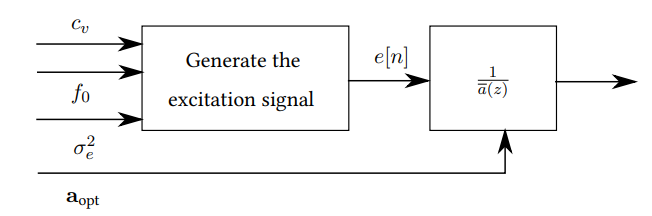

### 3) Signal processing and effects

With the audio files loaded from before, we can use the blocks now.

First we plot the output of the analysis one:

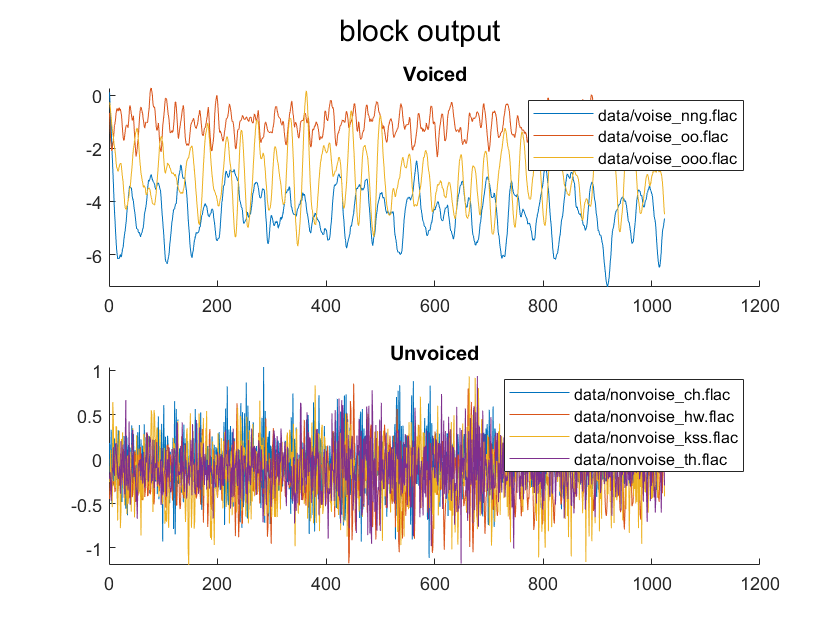

figure(26)
subplot(2,1,1)
sgtitle("block output")
hold on
ordervoice = 2;
orderunvoice = 10;
voiced_s2 = zeros(1,3);
voiced_pitchs = zeros(1,4);
unvoiced_s2 = zeros(1,3);
unvoiced_pitchs = zeros(1,4);
for i=1:3
    aud = voiced_audios(i,:);
    [voiced_pitchs(i),voiced_s2(i),predicteda] = BlockAnalysis(aud,ordervoice);
    predicted = filter(1, [1 -predicteda'], sqrt(predictedv).*rand(1,1024));
    predicted = aud - predicted;
    %[errorAutocorr, xp] = BiasedCrossCorr(predicted);
    plot(predicted)
end
title("Voiced")
legend(string(voiced_names), "Interpreter","none")
subplot(2,1,2)
hold on
for i=1:4
    aud = unvoiced_audios(i,:);
    [unvoiced_pitchs(i),unvoiced_s2(i),predicteda] = BlockAnalysis(aud,ordervoice);
    predicted = filter(1, [1 -predicteda'], sqrt(predictedv).*rand(1,1024));
    predicted = aud - predicted;
    %[errorAutocorr, xp] = BiasedCrossCorr(predicted);
    plot(predicted)
end
title("Unvoiced")
legend(string(unvoiced_names), "Interpreter","none")

it looks like something we could expect. For the voiced sounds, it appears like a sinusoid with random phase, and the unvoiced ones it looks a lot like white noise. So it is possible to recover the signal with the function BlockAnalysis.

Now, for testing all, we are going to use both functions and compare the input signal with the reconstructed one:

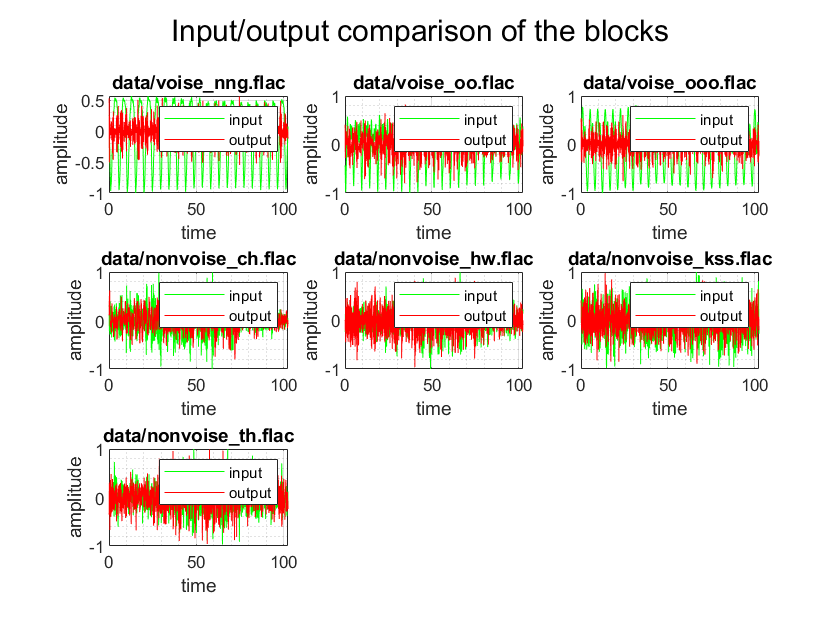

%inputs
signals = [voiced_audios ; unvoiced_audios];
orders = [2 2 2 10 10 10 10];

%outputs
estimateds = zeros(7,1024);

%extra values
titles = [voiced_names unvoiced_names];
x_label = "time";
y_label = "amplitude";
legends = ["input" "output"];

%graph procedure
figure(27)
for i=1:7
    subplot(3,3,i)
    signal = zeros(1,1024);
    for j = 256:256:1025
        [pitch,sigma2,Aopt] = BlockAnalysis(signals(i,(j-256+1):j),orders(i));
        result = BlockSynthesis(pitch,sigma2,Aopt,256);
        signal(j-255:j) = result;
    end
    plot(x_axis_t,signals(i,:),"g",x_axis_t,signal,"r")
    title(titles(i), "Interpreter","none")
    xlabel(x_label)
    ylabel(y_label)
    legend(legends)
    grid on
    grid minor
    sgtitle("Input/output comparison of the blocks")
    
    estimateds(i,:) = signal;
end

Here, we can see that the signal that enters the block and the output of the operations get us similar signals. The general shape looks like the same, but when we zoom in, the output signal can not adjust to the signal when its like a sine that on the top it is flat but oscilating. 

For the unvoiced sounds, the overall shape it is similar, but we can not say anything more as the output is an AR signal. At the end, we generated something similar, but not perfect.